# graph_NT.mlx

`../output/kob_test_36sec_NT.csv`の図示

NT

`graph.m`は内容同じ

clear;
close all;

df = readtable('../output/kob_test_36sec_NT.csv');
head(df)

ans = 8×19 table
         time            day        short_radi    salinity_wc    salinity_pw    sal_equiv_sav_total    osm_sav     tide        psi_wc         psi_pw       psi_sav_total    theta_sav    psi_sav_p     psi_sav_pi      Jv_leaf      Jv_rhizome      dV_sum          Pg            R    
    ______________    __________    __________    ___________    ___________    ___________________    _______    _______    ___________    ___________    _____________    _________    __________    ___________    __________    __________    ___________    _________    _________

    {'0D09:59:59'}             0      831.85         34.99         33.498              34.99           37.431     0.59918    -2.4818e+06    -2.3726e+06     -2.4818e+06      0.71179     1.7943e+05    -2.6612e+06    -0.0016149    -0.0030112              0    0.0066137    0.0060056
    {'0D10:00:35'}    0.00041667      833.35        34.987         33.497             34.992           37.433     0.59893    -2.4816e+06    -2

height(df)

ans = 16801

row_count = transpose(1:1:height(df));
newNames = "row_count";
df = addvars(df,row_count,'NewvariableNames',newNames)

df = 16801×20 table
         time            day        short_radi    salinity_wc    salinity_pw    sal_equiv_sav_total    osm_sav     tide        psi_wc         psi_pw       psi_sav_total    theta_sav    psi_sav_p     psi_sav_pi      Jv_leaf      Jv_rhizome      dV_sum          Pg            R        row_count
    ______________    __________    __________    ___________    ___________    ___________________    _______    _______    ___________    ___________    _____________    _________    __________    ___________    __________    __________    ___________    _________    _________    _________

    {'0D09:59:59'}             0      831.85         34.99         33.498              34.99           37.431     0.59918    -2.4818e+06    -2.3726e+06     -2.4818e+06      0.71179     1.7943e+05    -2.6612e+06    -0.0016149    -0.0030112              0    0.0066137    0.0060056        1    
    {'0D10:00:35'}    0.00041667      833.35        34.987         33.497             34.992        

% df.hour = df.t_min / 60;
df.psi_wc = df.psi_wc / 1000000;
df.psi_pw = df.psi_pw / 1000000;
df.psi_sav_total = df.psi_sav_total / 1000000;
df.psi_sav_p = df.psi_sav_p / 1000000;
df.psi_sav_pi = df.psi_sav_pi / 1000000;

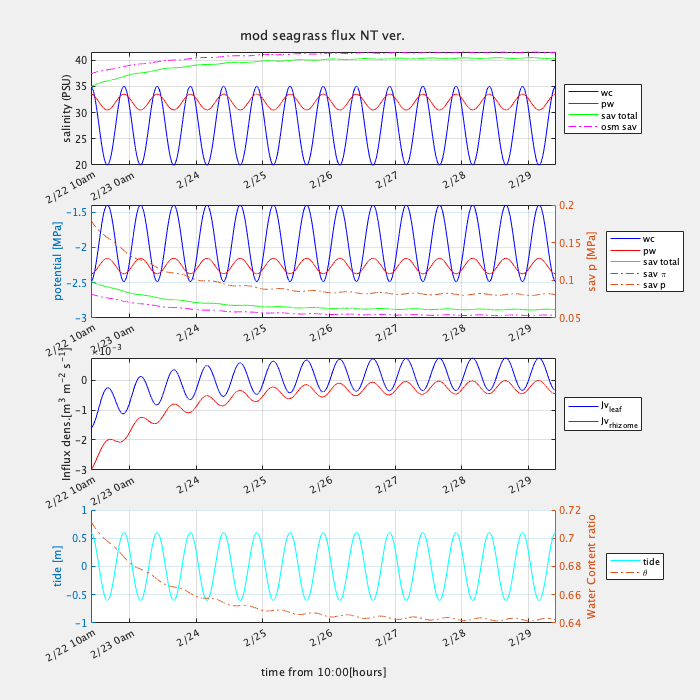

xl = [1 height(df)];

% for 1 day
% xticks_num = [1 301 601 901 1201 1501 1801 2101 2401];
% xticks_hourname = {'10:00','13:00','16:00','19:00','22:00','1:00','4:00','7:00','10:00'};

% for 1 week
xticks_num = [1 1401 3801 6201 8601 11001 13401 15801 18201 19201];
xticks_hourname = {'2/22 10am','2/23 0am','2/24','2/25','2/26','2/27','2/28','2/29','2/29 10am'};


figure('visible','on','Position',[100 100 700 700]);
tiledlayout(4,1)

sgtitle('mod seagrass flux NT ver.');

% subplot(4,1,1)
ax1 = nexttile;
x  = df.row_count;
y1 = df.salinity_wc;
y2 = df.salinity_pw;
y3 = df.sal_equiv_sav_total;
y4 = df.osm_sav;
plot(x,y1,'b',x,y2,'r',x,y3,'g',x,y4,'m-.')
% clear ylim
xlim(xl);
% ylim([33 38]);
xticks(xticks_num);
xticklabels(xticks_hourname);
% yticks([33 34 35 36 37 38]);
ylabel('salinity (PSU)');
legend('wc','pw','sav total','osm sav','Location',"eastoutside");
grid on;

% subplot(4,1,2)
ax2 = nexttile;
y4 = df.psi_wc;
y5 = df.psi_pw;
y6 = df.psi_sav_total;
y7 = df.psi_sav_pi;
y00 = df.psi_sav_p;
yyaxis left
plot(x,y4,'b-',x,y5,'r-',x,y6,'g-',x,y7,'m-.')
% ylim([-2.7 -2.3]);
% yticks([-2.7 -2.6 -2.5 -2.4 -2.3]);
ylabel('potential [MPa]');
yyaxis right
% plot(x,y00,'r-.')
plot(x,y00,'Color',[0.8500 0.3250 0.0980],"LineStyle","-.")
xlim(xl);
xticks(xticks_num);
xticklabels(xticks_hourname);
ylabel('sav p [MPa]')

legend('wc','pw','sav total','sav \pi','sav p','Location',"eastoutside");
grid on;

% subplot(4,1,3)
ax3 = nexttile;
y8 = df.Jv_leaf;
y9 = df.Jv_rhizome;
plot(x,y8,'b',x,y9,'r')
xlim(xl);
% ylim([0.2 0.6]);
xticks(xticks_num);
xticklabels(xticks_hourname);
% yticks([0.2 0.3 0.4 0.5 0.6]);
% clear xticklabels
% xticklabels({});
ylabel('Influx dens.[m^3 m^{-2} s^{-1}]');
legend('Jv_{leaf}','Jv_{rhizome}','Location',"eastoutside");
grid on;

% subplot(4,1,4)
ax4 = nexttile;
y10 = df.tide;
y11 = df.theta_sav;
hold on
yyaxis left
plot(x,y10,'Color','c','Marker','none')
clear ylim
ylim([-1 1])
% yticks([-1 0 1]);
ylabel('tide [m]');

yyaxis right
plot(x,y11,'Color',[0.8500 0.3250 0.0980],"LineStyle","-.")
% ylim([0.74999 0.75001])
% yticks([0.74999 0.75 0.75001]);
%ylim([0.751 0.753])
%yticks([0.751 0.752 0.753]);
ylabel('Water Content ratio');


xlim(xl);
xticks(xticks_num);
xticklabels(xticks_hourname);
xlabel('time from 10:00[hours]');
legend('tide','\theta','Location',"eastoutside");
grid on
hold off

linkaxes([ax1,ax2,ax3,ax4],'x');